# Exam B Question 4

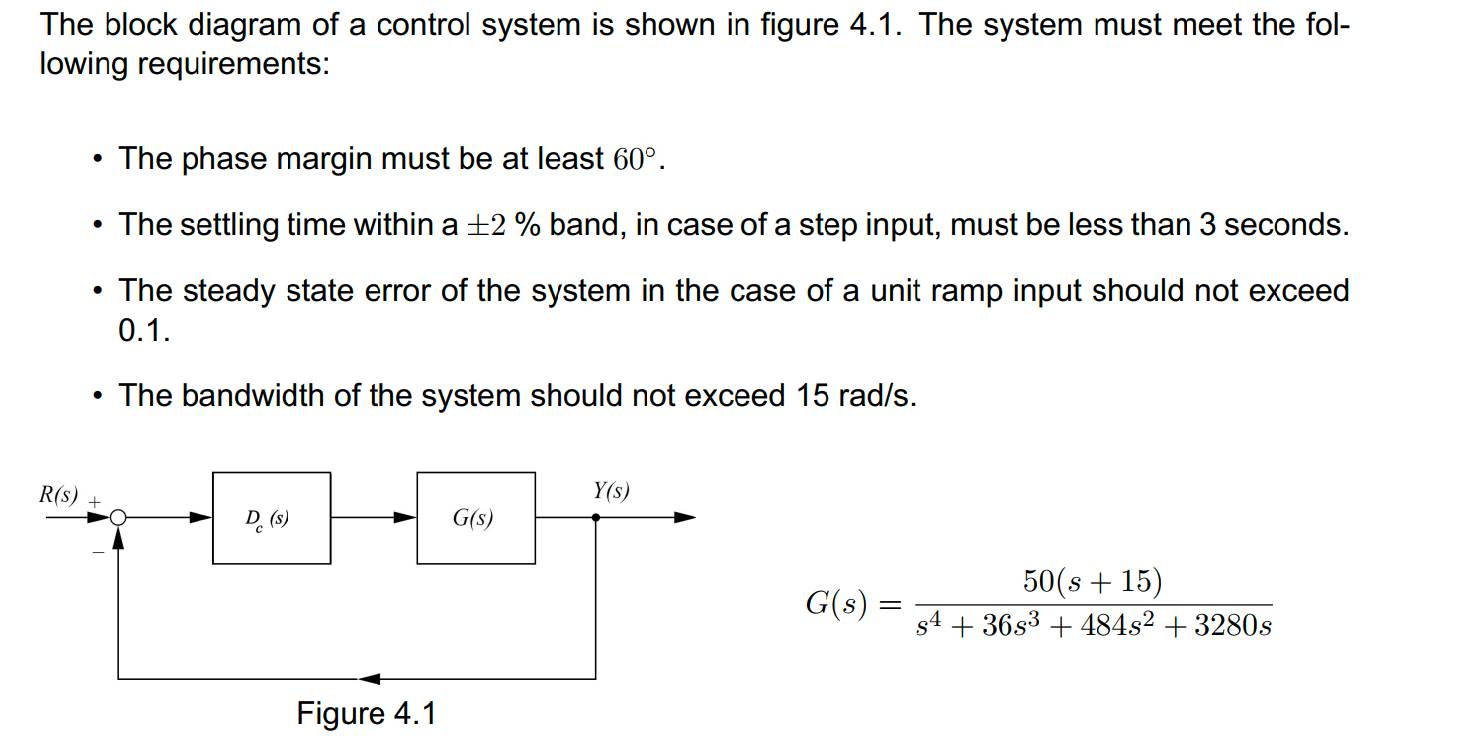

settling time $t_s \le 3s$


$$\begin{array}{l}
e_{\mathrm{Ss}} =\frac{A}{K_v }\le 0\ldotp 1\to K_v \ge 10\\
K_v =\lim_{s\to 0} \;s\;{\mathrm{KD}}_c G\left(s\right)=\frac{50\cdot 15}{3280}=0\ldotp 2287
\end{array}$$


The gain is smaller than a factor of 43.7254


$$\begin{array}{l}
\mathrm{bandwidth}\;\omega_{\mathrm{BW}} \\
\mathrm{PM}\ge 60\degree 
\end{array}$$



$$t_s =\frac{4\ldotp 6}{\zeta \omega_n }$$



clearvars, clc, close all
G = 50*tf([1 15], [1, 36, 484, 3280, 0])


G =
 
            50 s + 750
  -------------------------------
  s^4 + 36 s^3 + 484 s^2 + 3280 s
 
Continuous-time transfer function.


K1 =  43.7525;

T = feedback(K1*G,1)


T =
 
              2188 s + 3.281e04
  ------------------------------------------
  s^4 + 36 s^3 + 484 s^2 + 5468 s + 3.281e04
 
Continuous-time transfer function.


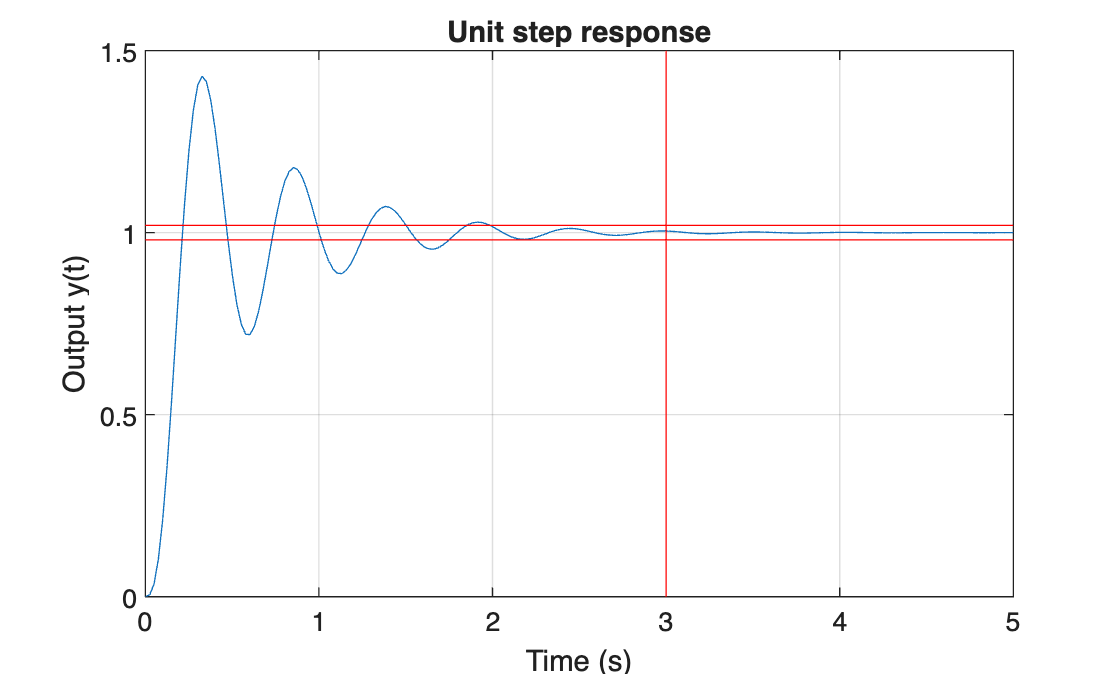

tt = linspace(0.0,5.0,200);
y = step(T,tt);
figure(1)
plot(tt,y)
hold on
%plot([tt(1), tt(end)],[1.05, 1.05],'g')
plot([tt(1), tt(end)],[1.02, 1.02],'r')
plot([tt(1), tt(end)],[0.98, 0.98],'r')
plot([3,3],[0,1.5],'r')
grid on
xlabel('Time (s)')
ylabel('Output y(t)')
title('Unit step response')

We can see the settling time and overshoot in figure 1 doesn't meet the requirements.

figure(2)
omega = logspace(0,2,400);
[mag1,phase1] = bode(K1*G,omega);
mag1 = squeeze(mag1);
phase1 = squeeze(phase1);
subplot(2,1,1),semilogx(omega,20*log10(mag1))
xlabel('Angular frequency \omega (rad/s)'),ylabel('20log|G(\omega)|')
hold on
grid on
title('Plant (open loop) transfer function bode diagram')
subplot(2,1,2),semilogx(omega,phase1)
xlabel('Angular frequency \omega (rad/s)'),ylabel('\phi')
grid on
[Gm,Pm,omegcp,omegcg] = margin(K1*G);
dBGm = 20*log10(Gm);
disp(['System phase margin (degrees): ',num2str(Pm)])

System phase margin (degrees): 27.5702


disp(['System cross over angular frequency (rad/s): ',num2str(omegcg)])

System cross over angular frequency (rad/s): 10.174


disp(['System gain margin (dB): ',num2str(dBGm)])

System gain margin (dB): 4.7056


disp(['System Phase Crossover Frequency (rad/s):',num2str(omegcp)])

System Phase Crossover Frequency (rad/s):13.9847



% check the bandwidth of the system
Tuc = feedback(K1*G, 1)


Tuc =
 
              2188 s + 3.281e04
  ------------------------------------------
  s^4 + 36 s^3 + 484 s^2 + 5468 s + 3.281e04
 
Continuous-time transfer function.



figure(5)
omega5 = logspace(-1,2,400);
[mag5,phase5] = bode(Tuc,omega5);
mag5 = squeeze(mag5);
phase5 = squeeze(phase5);

semilogx(omega5, 20*log10(mag5), 'DisplayName','Gain adjust uncompensated')
xlabel('Angular frequency \omega (rad/s)');
ylabel('20log|T(\omega)|')
hold on
grid on
title('System (close loop) transfer function bode diagram')
semilogx([omega5(1),omega5(end)],[-3,-3],'r')
axis([.1, 100, -50, 50])
bw = bandwidth(Tuc)

bw = 16.1428

bandwidth are read in 16.15

Since the phase margin of the gain we need is $60\degree$, It is suggested that we add a measure of safety of 5 degree, so  I decided to start off my design iteration with the value of ${\omega_c }^{\prime }$ at the which PM is $-180\degree +60\degree +5\degree =-115\degree$

target_phase = -115

target_phase = -115

figure(2)
subplot(2,1,2)
hold on
semilogx([omega(1),omega(end)],[target_phase,target_phase],'k')
hold off


$$z=\frac{1}{T_I }=\frac{{w_c }^{\prime } }{10}=0\ldotp 491,T_I =2\ldotp 0357$$


When ${w_c }^{\prime } =4\ldotp 912$4, $20\log \left(G\left(\omega \right)\right)=$ -6.6058

$\textrm{attentuation}=-20\textrm{log10}\left(\alpha \;\right)\Rightarrow \alpha =$2.1394

% find omega c prime
wc_prime = interp1(phase1, omega, target_phase);
T_I = 10/wc_prime

T_I = 2.0357

z = 1/ T_I;
disp(['omega_c_prime at target PM is: ',num2str(wc_prime)])

omega_c_prime at target PM is: 4.9124


[alpha,~] = bode(K1*G, wc_prime)

alpha = 2.1273

alpha_dB = 20*log10(alpha)

alpha_dB = 6.5567

prnstr = "The gain adjusted uncompensated system is %2.2f dB higher than 0 dB\n\t at omega_c_p (the " + ...
    "length of the red line below.)\n\n";
fprintf(1,prnstr,alpha_dB)

The gain adjusted uncompensated system is 6.56 dB higher than 0 dB
	 at omega_c_p (the length of the red line below.)



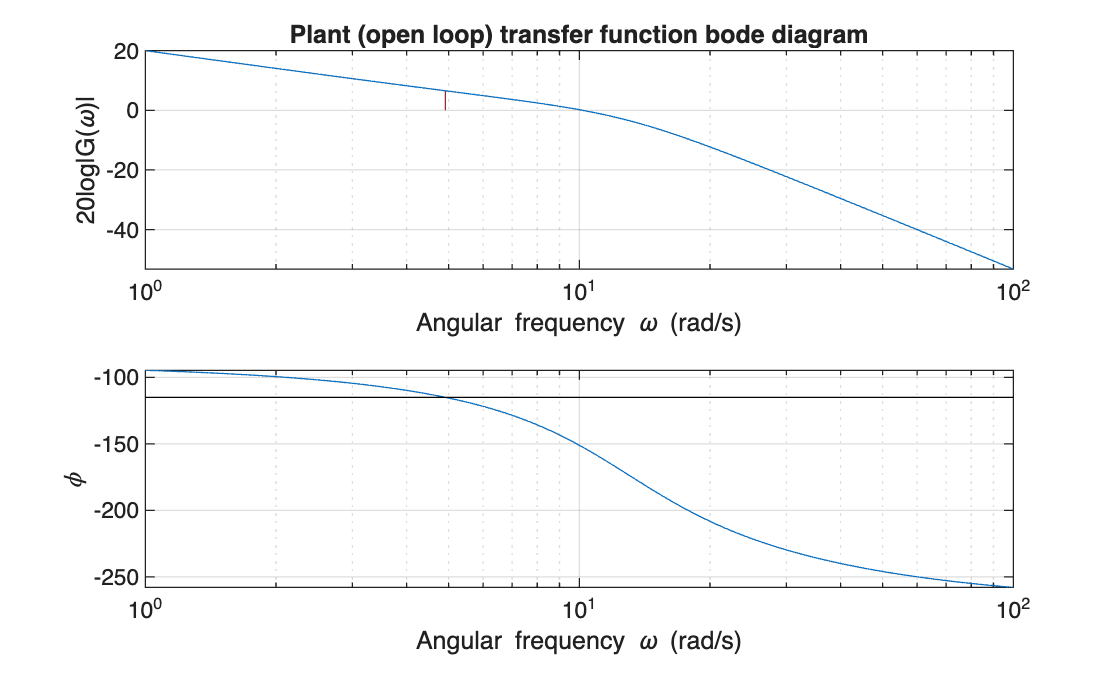


figure(2)
subplot(2,1,1)
hold on 
semilogx([wc_prime,wc_prime],[0,alpha_dB],'r')
hold off

Now the design compensator can be defined as transfer function

Dc = tf([T_I,1],[alpha*T_I ,1])


Dc =
 
  2.036 s + 1
  -----------
  4.331 s + 1
 
Continuous-time transfer function.


Calculate the pole as $p=\frac{1}{\alpha \;T_I }=\frac{z}{\alpha }$

p = 1/(alpha*T_I);
disp("Lag compensator zero = -"+num2str(z)+"rad/s")

Lag compensator zero = -0.49124rad/s


disp('compensator loop transfer function:')

compensator loop transfer function:


Gt = Dc*K1*G


Gt =
 
              4453 s^2 + 6.899e04 s + 3.281e04
  --------------------------------------------------------
  4.331 s^5 + 156.9 s^4 + 2132 s^3 + 1.469e04 s^2 + 3280 s
 
Continuous-time transfer function.


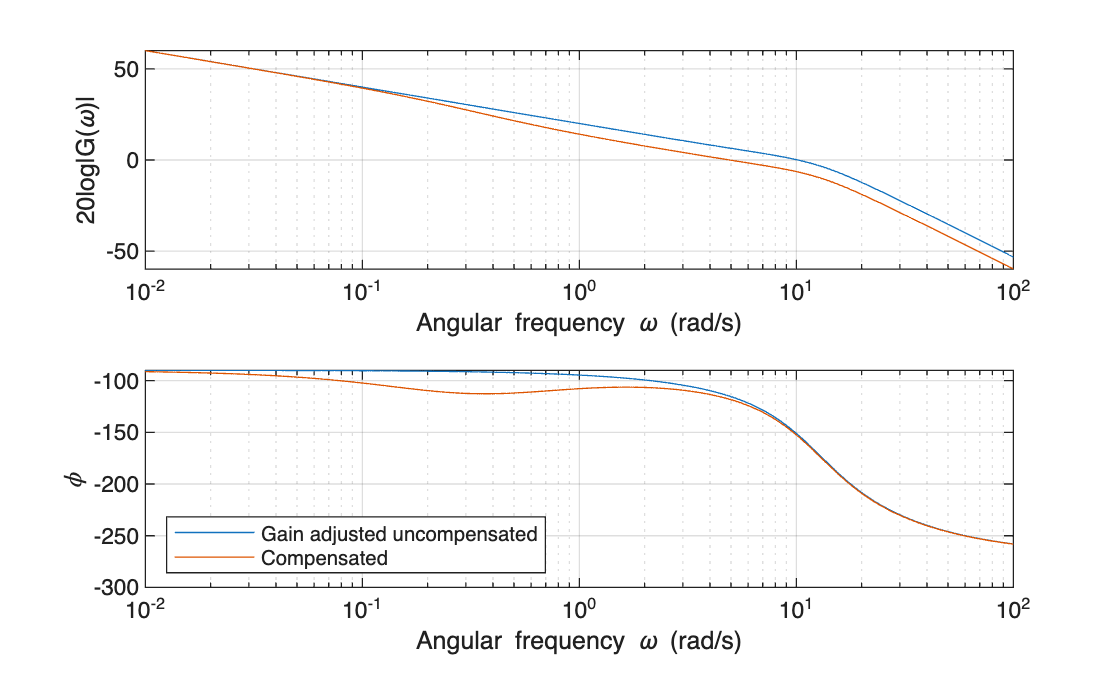


figure(3)
title('Loop transfer functions Bode diagrams')
omega = logspace(-2,2,400);
[mag1,phase1] = bode(K1*G,omega);
mag1 = squeeze(mag1);
phase1 = squeeze(phase1);
[mag2,phase2] = bode(Gt,omega);
mag2 = squeeze(mag2);
phase2 = squeeze(phase2);
subplot(2,1,1)
semilogx(omega,20*log10(mag1))
hold on
semilogx(omega,20*log10(mag2))
hold off
grid on
xlabel('Angular frequency \omega (rad/s)'),ylabel('20log|G(\omega)|')
subplot(2,1,2)
semilogx(omega,phase1)
hold on
semilogx(omega,phase2)
hold off
grid on
xlabel('Angular frequency \omega (rad/s)'),ylabel('\phi')
legend('Gain adjusted uncompensated','Compensated',...
'Location','southwest')

Check the phase margin

[Gm,Pm,omegcp,omegcg] = margin(Gt);
dBGm = 20*log10(Gm);
disp(['System phase margin (degrees): ',num2str(Pm)])

System phase margin (degrees): 61.8729


disp(['System cross over angular frequency (rad/s): ',num2str(omegcg)])

System cross over angular frequency (rad/s): 4.9325


disp(['System gain margin (dB): ',num2str(dBGm)])

System gain margin (dB): 11.0393


disp(['System Phase Crossover Frequency (rad/s):',num2str(omegcp)])

System Phase Crossover Frequency (rad/s):13.8157


Thus the system transfer function( the close loop transfer function) is:

T2 = feedback(Gt,1)


T2 =
 
                     4453 s^2 + 6.899e04 s + 3.281e04
  -----------------------------------------------------------------------
  4.331 s^5 + 156.9 s^4 + 2132 s^3 + 1.914e04 s^2 + 7.227e04 s + 3.281e04
 
Continuous-time transfer function.


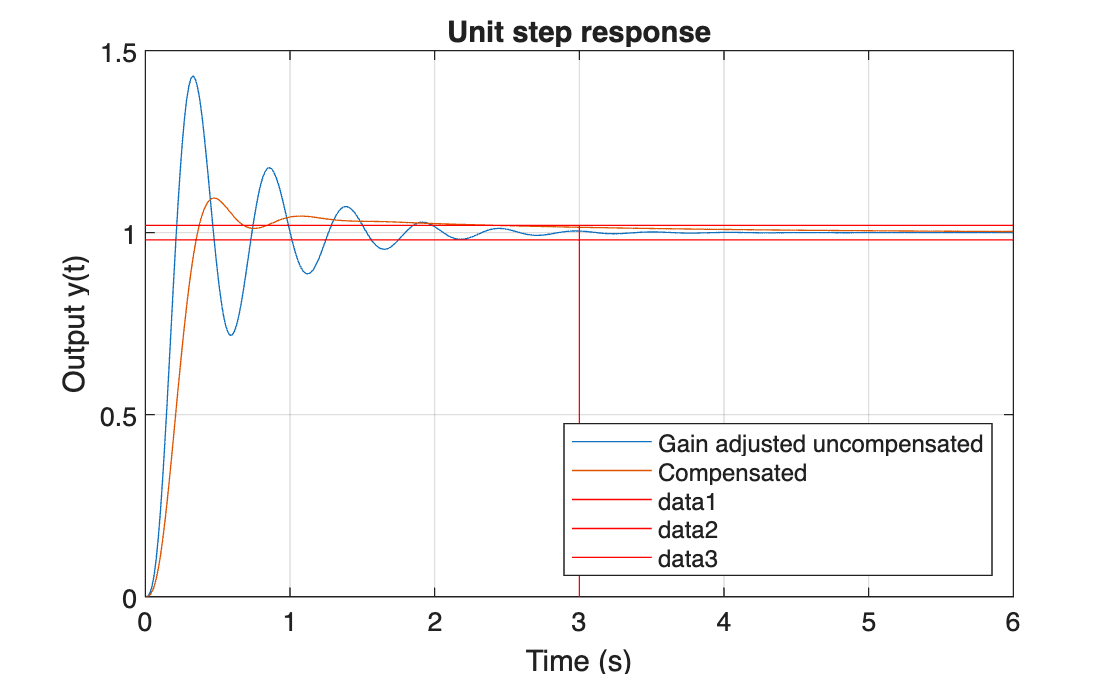


tt = linspace(0.0,6,400);
y1 = step(Tuc,tt);
y2 = step(T2,tt);
figure(4)
plot(tt,y1,'DisplayName','Gain adjusted uncompensated')
hold on
plot(tt,y2,'DisplayName','Compensated')
% plot([tt(1), tt(end)],[1.05, 1.05],'g')
plot([tt(1),tt(end)],[1.02, 1.02],'r')
plot([tt(1),tt(end)],[0.98, 0.98],'r')
plot([3.0,3.0],[0.0, 1.02],'r')
grid on
xlabel('Time (s)')
ylabel('Output y(t)')
title('Unit step response')
legend('Location','southeast')
hold off

Check the bandwidth of the system:

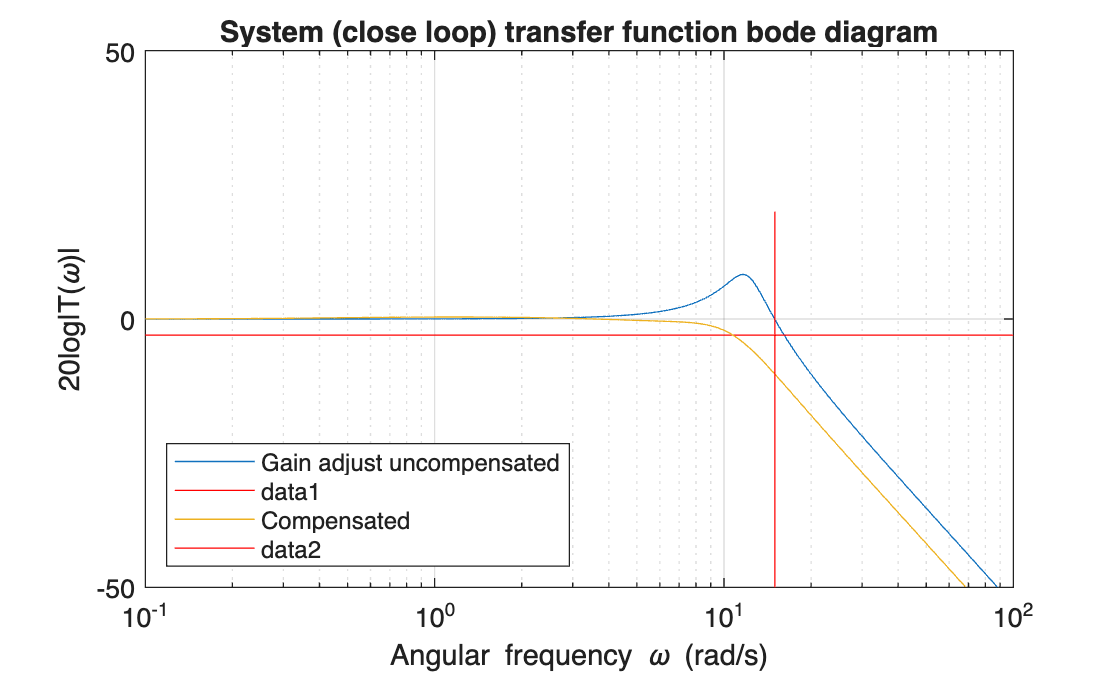

figure(5)
[mag52,phase52] = bode(T2,omega5);
mag52 = squeeze(mag52);
phase52 = squeeze(phase52);
semilogx(omega5,20*log10(mag52),'DisplayName','Compensated')
semilogx([15.0,15.0],[-50,20],'r')
hold off
legend('Location','southwest')

bw2 = bandwidth(T2)

bw2 = 10.7318

Lastly the gain $K=43\ldotp 7254$ is detached from the plant and attached to the compensator,  to properly define the compensator as designed: 

disp('Compensator as designed')

Compensator as designed


Dc = minreal(K1*Dc)


Dc =
 
  20.57 s + 10.1
  --------------
    s + 0.2309
 
Continuous-time transfer function.



Dcnum = Dc.num{1};
shouldbezero = Dcnum(2)/Dcnum(1) - z

shouldbezero = -5.5511e-17

K = Dcnum(1)

K = 20.5669

z

z = 0.4912

p

p = 0.2309